# LineSelector

**Overview**

The `LineSelector` chart manages multiple line plots, for which the *y*-data is on possibly different scales.The chart data comprises a numeric vector (`XData`) together with a numeric data matrix (`YData`). Each column of the `YData` is plotted against the `XData`, using a normalized scale so that all lines are visible together. Clicking on a line highlights it and shows its *y*-data on the true scale via *y*-axis limits and ticks. Clicking on another line changes the selection. Lines can be selected by clicking on the line itself, or programmatically by changing the `SelectedLineIndex` property of the chart.

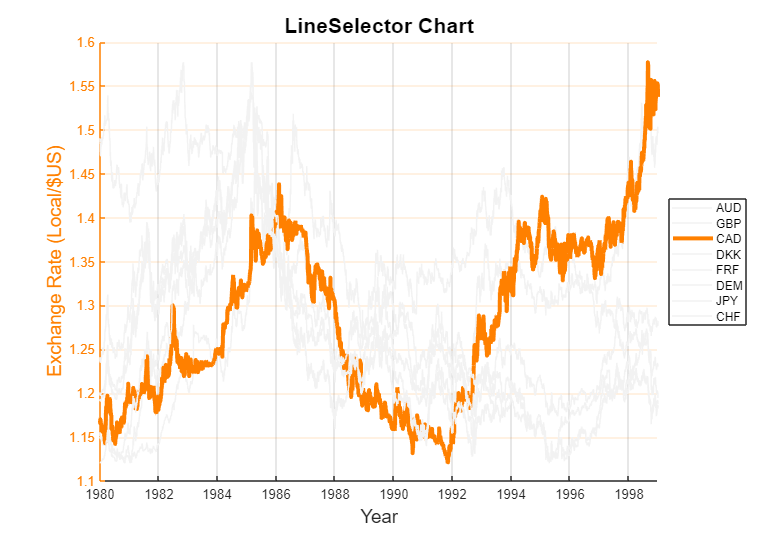

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "LineSelector.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "LineSelector.m"))) the source code for the `LineSelector` chart.

See also:

- [stackedplot](matlab: doc("stackedplot")): An existing MATLAB chart for creating a stacked plot of several variables with a common x-axis.

## Load and prepare the exchange rate data.

The data comprises a timetable of exchange rates (local currency per $US) for eight currencies.

load( fullfile( catalogRoot(), "data", "Exchange.mat" ), "T" )

Create a numeric time vector, in fractional years, for use with the chart.

startDate = min( T.Date );
yearStart = dateshift( startDate, "start", "year" );
yearEnd = dateshift( startDate, "end", "year" );
fracYear = days( startDate - yearStart ) / days( yearEnd - yearStart );
t = startDate.Year + fracYear + years( T.Date - startDate );

Extract the currency codes.

codes = T.Properties.VariableNames;

## Create a figure for the chart.

f = exampleFigure( "Name", "LineSelector Example", ...
    "Color", "w" );

## Create the chart, specifying the data, figure and legend entries.

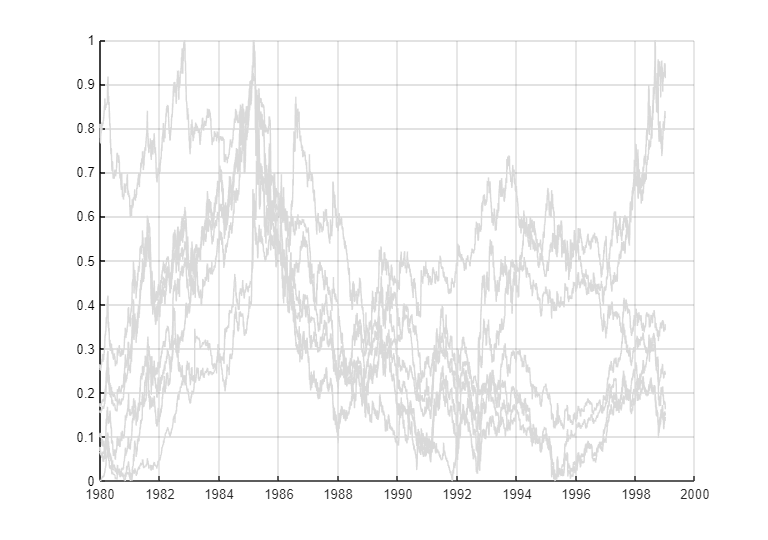

LS = chart.LineSelector( "Parent", f, ...
    "XData", t, ...
    "YData", T.Variables );

## Annotate the chart and customize its appearance.

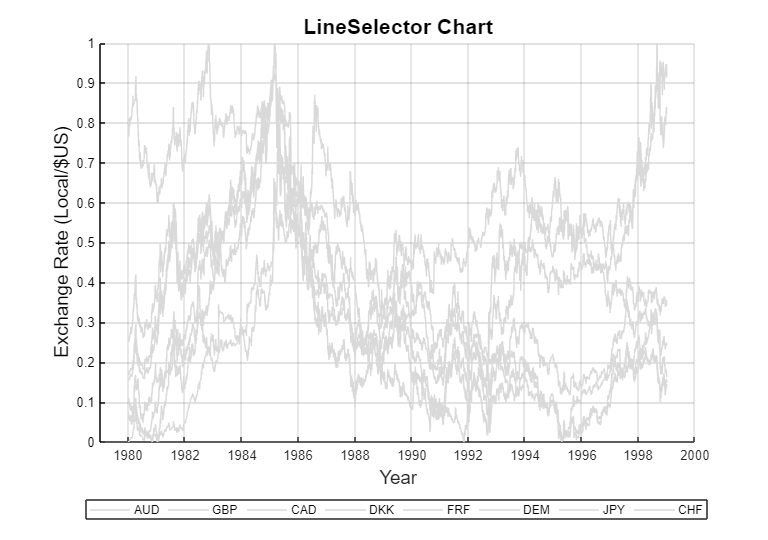

xlabel( LS, "Year", "FontSize", 14 )
ylabel( LS, "Exchange Rate (Local/$US)", "FontSize", 14 )
title( LS, "LineSelector Chart", "FontSize", 16 )
xlim( LS, [1979, 2000] )
legend( LS, codes, "Location", "southoutside", ...
    "Orientation", "horizontal" )

## Change the chart data to show a particular decade.

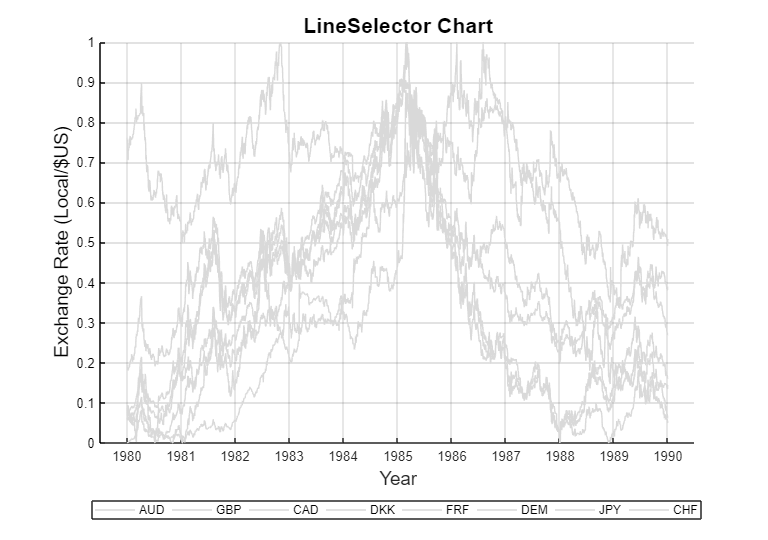

LS.YData = LS.YData(LS.XData >= 1980 & LS.XData < 1990, :);
xlim( LS, [1979.5, 1990.5] )

## Show Australian and Canadian dollar exchange rates only.

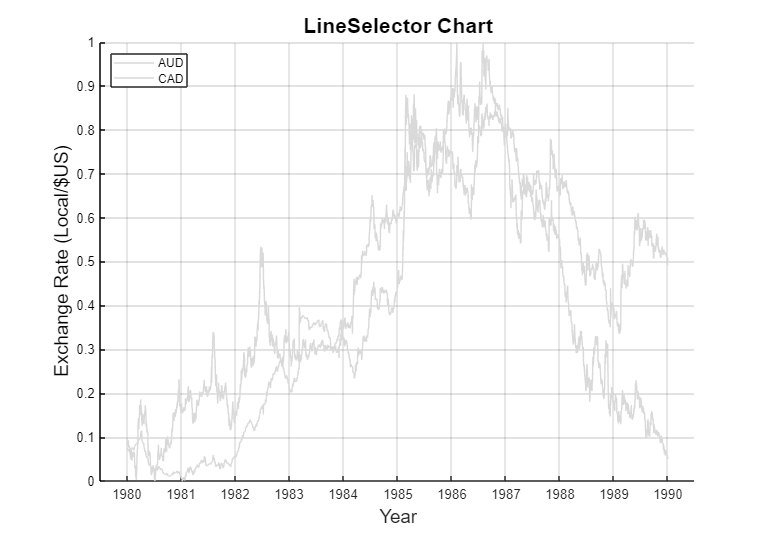

AUDCAD = ["AUD", "CAD"];
LS.YData = LS.YData(:, ismember( codes, AUDCAD ));
legend( LS, AUDCAD, "Location", "northwest", ...
    "Orientation", "vertical" )

## Select a currency to highlight.

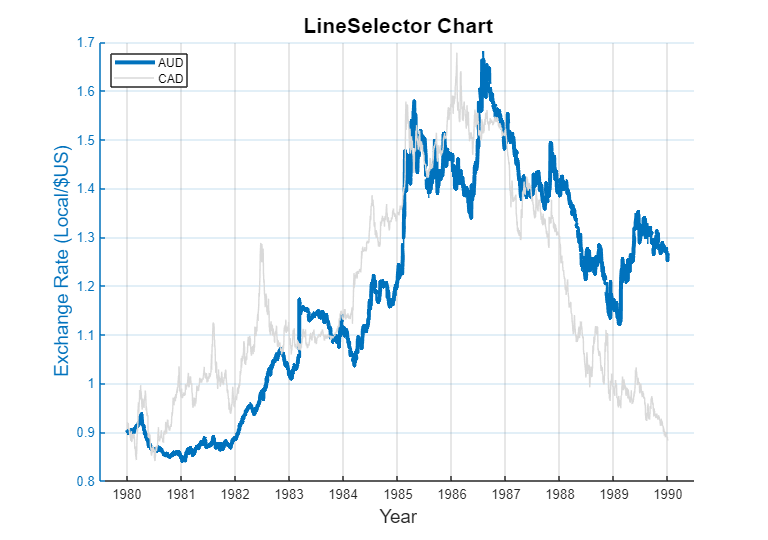

LS.SelectedLineIndex = 1;

## Change the selection and highlight color.

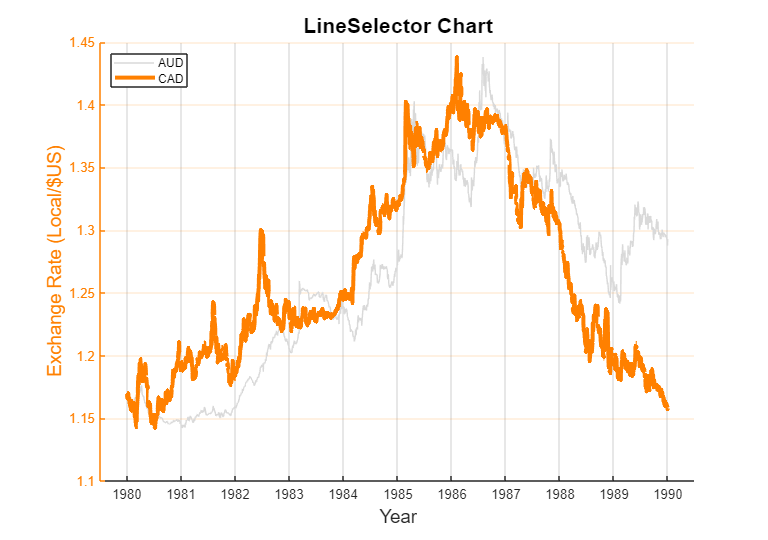

set( LS, "SelectedLineIndex", 2, ...
    "SelectedColor", [1, 0.5, 0] )

## Include more lines in the chart, update the legend text and set the x-axis limits automatically.

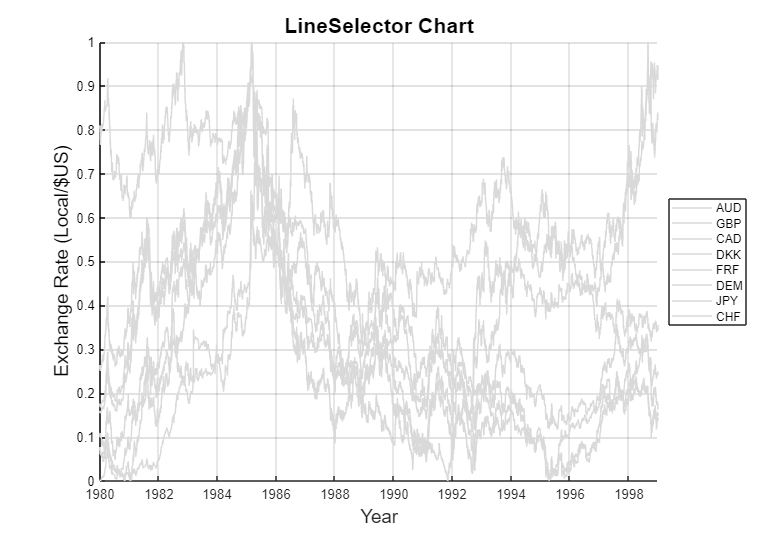

set( LS, "XData", t, ...
    "YData", T.Variables )
drawnow()
legend( LS, codes, "Location", "eastoutside" )
xlim( LS, [-Inf, Inf] )

## Select a currency and change the color of the unselected lines.

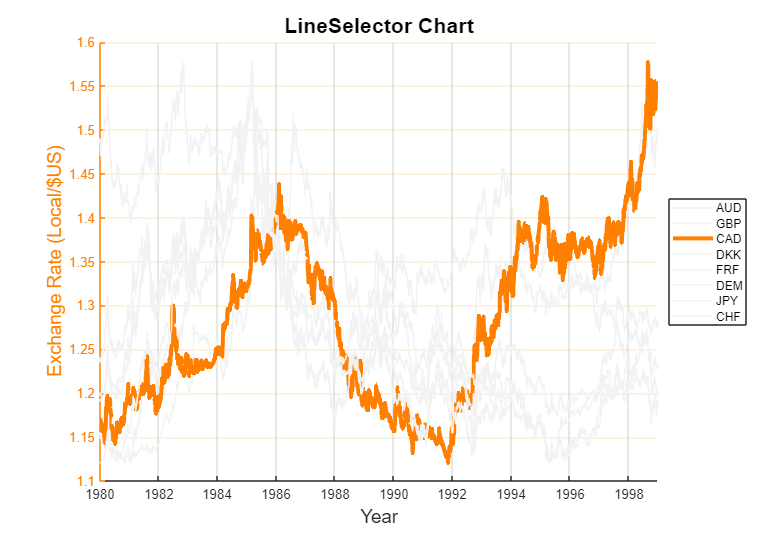

LS.SelectedLineIndex = 3;
LS.TraceColor = 0.95 * ones( 1, 3 );

## Deselect the line.

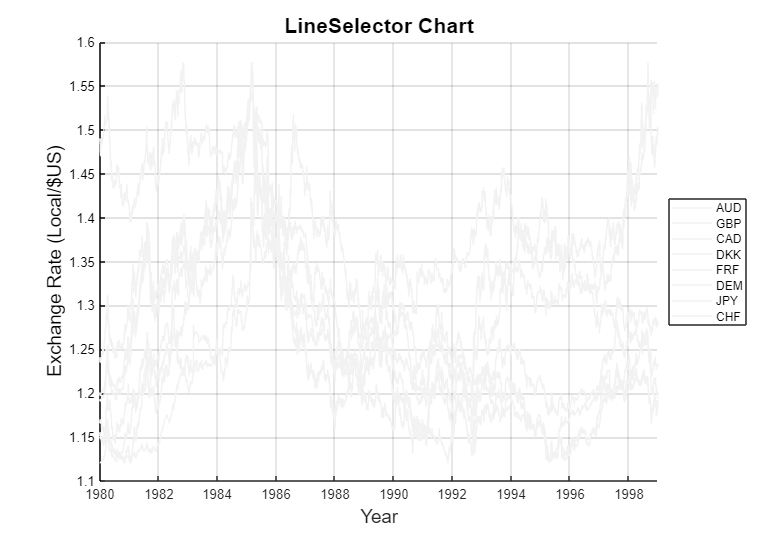

LS.SelectedLineIndex = 0;

*Copyright 2018-2021 The MathWorks, Inc.*